## Confidence intervals

First we create the fake background that is a Poisson background with mean 100 and 5000 data points.

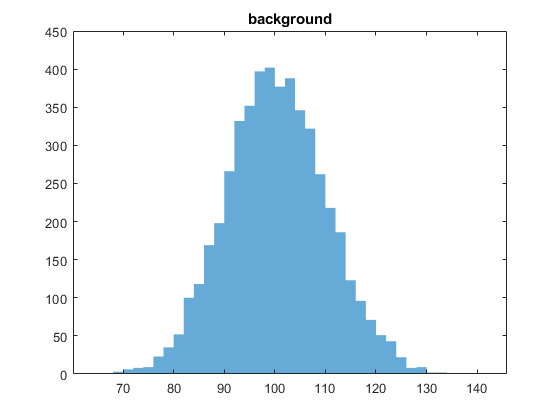

clc; clear; close all;
PoissonMean100 = makedist('Poisson',"lambda",100);
BackgroundData = random(PoissonMean100,[1 5000]);
figure;
histogram(BackgroundData,"EdgeColor","none");
title('background');

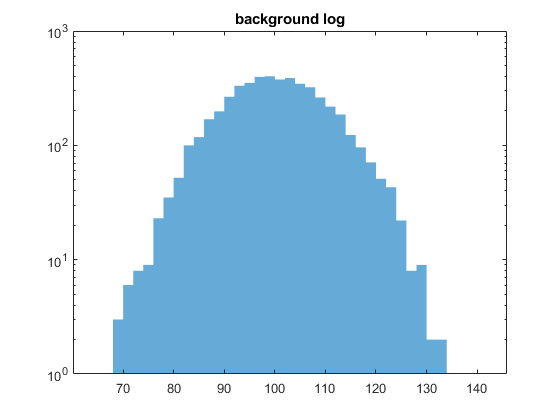

figure;
histogram(BackgroundData,"EdgeColor","none");
set(gca,'YScale',"log");
title('background log');

**Problem 1**

The first problem is to check the background distribution and determine where the 5σ sensitivity threshold is. 

From Z table we know the Probability for 5 sigma is 2.8571e-7. We use inverse cumulative of Poisson distribution function to find the thresh hold for 5 sigma. We get the thresh hold at 154

Prob5Sigma = 2.8571e-7

Prob5Sigma = 2.8571e-07


Thresh5Sigma = icdf(PoissonMean100,1-Prob5Sigma)

Thresh5Sigma = 154

**Problem 2**

We simulated a set of injected signals of a *single strength*. I make my simulated signal around 8 sigma (190). Inject this signal into your background data many times.

b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?

Prob8Sigma = 6.22096e-16

Prob8Sigma = 6.2210e-16

Thresh8Sigma = icdf(PoissonMean100,1-Prob8Sigma)

Thresh8Sigma = 190

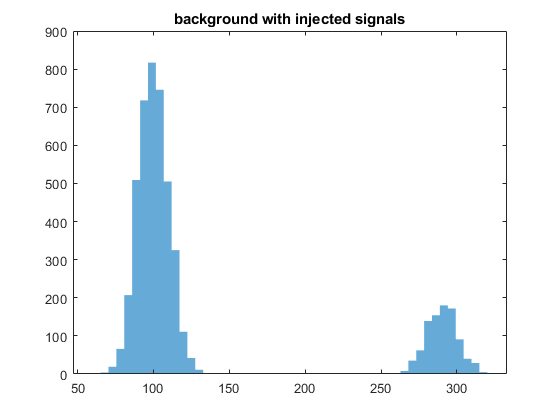

size = 5000;
signal = zeros(1,size);
signal(randi(numel(signal),[1,1000])) = 190;
obssiganl = BackgroundData + signal;
figure;
histogram(obssiganl,50,"EdgeColor","none")
title('background with injected signals');

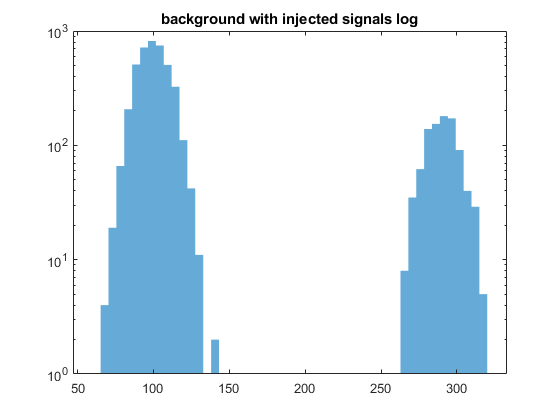

figure;
histogram(obssiganl,50,"EdgeColor","none");
set(gca,'YScale',"log");
title('background with injected signals log');

**Problem 3**

Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). 

a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal

b) If you choose the same injected signal power as in problem 2, show that you get the same answer.

c) Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.

d) For your observed signal, what is the 1σ uncertainty on the true signal strength?

e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?

BackgroundData2 = random(PoissonMean100,[1000 1000]);
signalstrength = linspace(0,500,1000);
[scratch, signal2] = meshgrid(signalstrength);
obssignal2 = BackgroundData2 + signal2

obssignal2 =   106.0000  103.0000   79.0000   91.0000  110.0000  104.0000  111.0000  127.0000   85.0000   91.0000   96.0000  100.0000   94.0000  101.0000  104.0000  103.0000   91.0000  101.0000  102.0000   95.0000  105.0000  108.0000  108.0000   92.0000  106.0000  117.0000   89.0000   93.0000  100.0000  102.0000  101.0000  112.0000  106.0000  109.0000  105.0000  114.0000  110.0000   93.0000   86.0000  108.0000   99.0000  102.0000   91.0000  100.0000   97.0000  101.0000  102.0000   97.0000   82.0000  109.0000
   98.5005  109.5005   89.5005   87.5005   94.5005  100.5005   95.5005  110.5005  100.5005  112.5005   97.5005   95.5005  103.5005   84.5005   96.5005  104.5005  111.5005   95.5005  120.5005  124.5005   86.5005  113.5005   84.5005   96.5005  106.5005  108.5005  111.5005   96.5005  106.5005  126.5005   90.5005  106.5005  112.5005  101.5005  120.5005   89.5005  116.5005   99.5005  103.5005  108.5005  106.5005  111.5005  100.5005  105.5005   96.5005  122.5005   98.5005   95.5005   87.

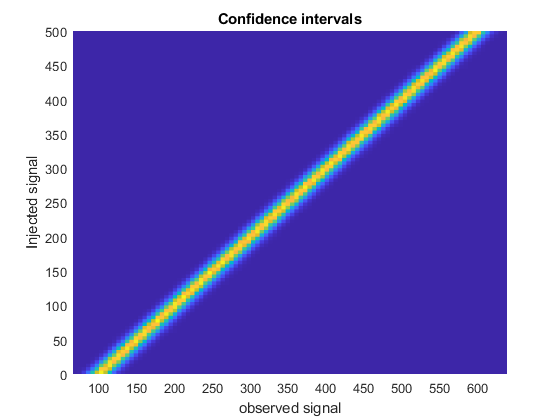

figure;
h = histogram2(obssignal2,signal2,100,'DisplayStyle','tile','ShowEmptyBins','on');
ylabel("Injected signal")
xlabel("observed signal")
title("Confidence intervals")

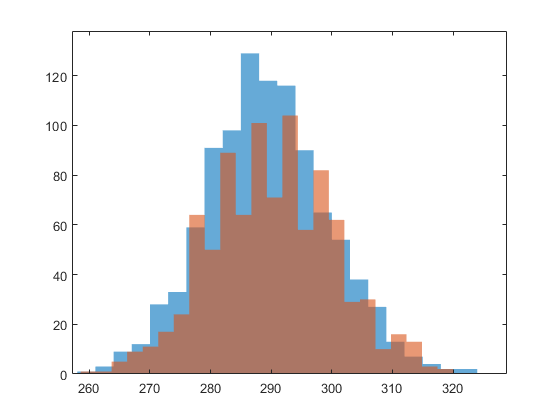

figure;
histogram(obssignal2(380,:),'EdgeColor',"none");
hold on
histogram(obssiganl,100,"EdgeColor","none")
xlim([257.3 328.9])
ylim([0 138])